# **Second Optimal Control Project**

# **Designing a Discrete Finite-Time LQR for a Linear 1/4-Car System**

## Ali Eidizadeh                            ali80ei@gmail.com

## Amirhadi Keyvan     amirhadikeyvan@gmail.com

clear all;
close all;
clc

% System definition
A = [0 1 0 0;
     0 -0.14 -32 0.14;
     0 1 0 -1;
    -1562.5 1.0937 1812.5 -48.0312];

B = [0;
     0.0004;
     0;
    -0.0031];

C = [1 0 0 0;
     0 1 0 0;
     0 0 1 0];
D = zeros(size(C, 1), size(B, 2));

T = 60;
Ts = 0.01;
N = T/Ts;
sys = ss(A,B,C,D);
sysd = c2d(sys,Ts);
A = sysd.A;
B = sysd.B;
C = sysd.C;
D = sysd.D;

rank(ctrb(A,B))

ans = 4

rank(obsv(A,C))

ans = 4

% Cost function matrices
Q = C'*C;
R = 1;
F = zeros(N-1, size(A,2));  % (time, states)

% Riccati recursion
P = Q;
for k = N-1:-1:1
    F(k,:) = - (R + B'*P*B) \ (B'*P*A);  % 1 x n
    P = A'*P*A + Q - A'*P*B * inv(R + B'*P*B) * B'*P*A;
end

X0 = [0.2; 0.2; 0.2; 0.2];  % Adjust as needed
x = zeros(size(A,1), N);
u = zeros(size(B,2), N-1);
y = zeros(size(C,1), N-1);
x(:,1) = X0;

% Forward simulation
for j = 1:N-1
    u(:,j) = F(j,:) * x(:,j);  % F(j,:) is 1 x n, x(:,j) is n x 1 → scalar u
    x(:,j+1) = A * x(:,j) + B * u(:,j);
    y(:,j) = C * x(:,j);
end

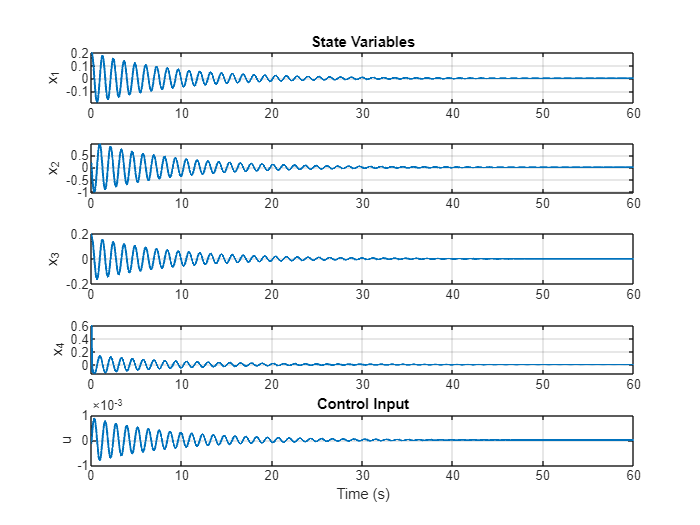

% Time vectors
t = Ts:Ts:T;          % For states (length N)
t_u = t(1:end-1);          % For control input and gain (length N-1)

% Plot all state variables
figure;
subplot(5,1,1);
plot(t, x(1,:), 'LineWidth', 1.2);
ylabel('x_1');
title('State Variables');
grid on;

subplot(5,1,2);
plot(t, x(2,:), 'LineWidth', 1.2);
ylabel('x_2');
grid on;

subplot(5,1,3);
plot(t, x(3,:), 'LineWidth', 1.2);
ylabel('x_3');
grid on;

subplot(5,1,4);
plot(t, x(4,:), 'LineWidth', 1.2);
ylabel('x_4');
grid on;

% Plot control input
subplot(5,1,5);
plot(t_u, u(1,:), 'LineWidth', 1.2);
ylabel('u');
xlabel('Time (s)');
title('Control Input');
grid on;

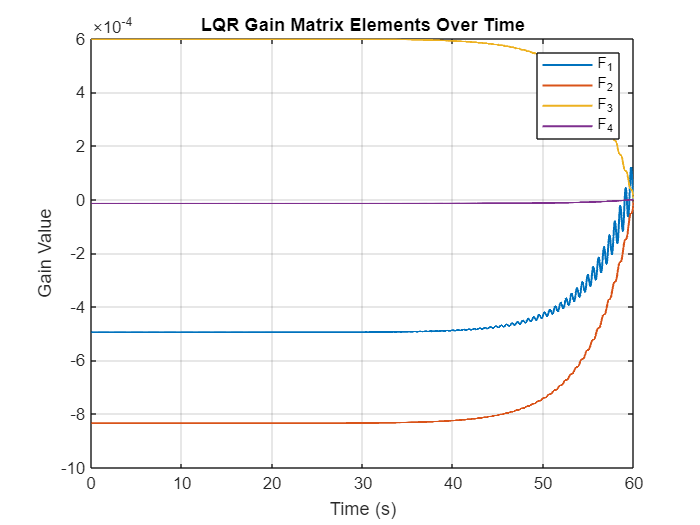


% Plot LQR gains over time
figure;
for i = 1:size(F,2)
    plot(t_u, F(:,i), 'LineWidth', 1.2);
    hold on;
end
xlabel('Time (s)');
ylabel('Gain Value');
title('LQR Gain Matrix Elements Over Time');
legend('F_1','F_2','F_3','F_4');
grid on;